QEA Final Project

Fisher Faces

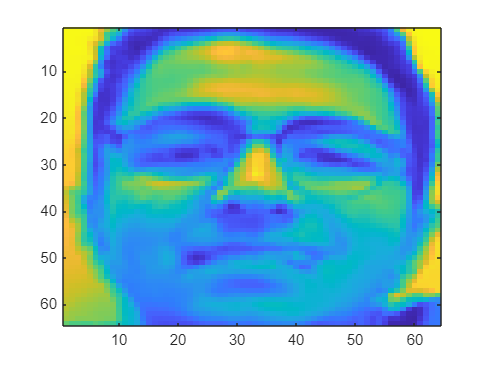

clear

load class_data_test.mat
load class_data_train.mat

% reshape images to 2d matrix - 4096x356 (4096 pixels, 356 faces)
trainfaces = reshape(grayfaces_train, size(grayfaces_train,1)*size(grayfaces_train,2),size(grayfaces_train,3));

% find the mean of each class - each class is a different subject/person
numclasses = max(subject_train);
meanclass = zeros(4096, numclasses); % 4096x89
j = 0;
temp = zeros(4096,1);
num = 1;
for i = 1:size(trainfaces, 2)
    if subject_train(i) == num
        j = j + 1;
        temp = temp + trainfaces(:,i);
    else
        meanclass(:,num) = temp/j;
        temp = trainfaces(:,i);
        j = 1;
        num = num + 1;
    end
end
meanclass(:,num) = temp/j; % for the last subject

% making sure meanclass works
testimage = reshape(meanclass(:,1), 64, 64);
imagesc(testimage(:,:))


% find scatter within classes
swithin = zeros(4096, 4096);
j = 1;
for i = 1:size(trainfaces, 2)
    if j == subject_train(i)
        inside = (trainfaces(:,i) - meanclass(:,j))*transpose(trainfaces(:,i) - meanclass(:,j));
        swithin = swithin + inside;
    else
        j = j + 1;
        inside = (trainfaces(i) - meanclass(:,j))*transpose(trainfaces(:,i) - meanclass(:,j));
        swithin = swithin + inside;
    end
end


% find scatter between classes
sbetween = zeros(4096);
for i = 1:numclasses
    inside = (meanclass(i) - mean(trainfaces, 2))*transpose(meanclass(i) - mean(trainfaces, 2));
    inside = inside * numclasses;
    sbetween = sbetween + inside;
end

A = inv(swithin);

B = A * sbetween;
[vectors, values] = eig(B)

vectors =    0.0007 + 0.0000i   0.0012 + 0.0000i   0.0002 + 0.0000i  -0.0000 + 0.0013i  -0.0000 - 0.0013i  -0.0003 + 0.0000i   0.0000 + 0.0019i   0.0000 - 0.0019i  -0.0039 - 0.0017i  -0.0039 + 0.0017i   0.0033 + 0.0022i   0.0033 - 0.0022i  -0.0023 - 0.0014i  -0.0023 + 0.0014i   0.0062 - 0.0054i   0.0062 + 0.0054i  -0.0034 + 0.0009i  -0.0034 - 0.0009i  -0.0006 - 0.0009i  -0.0006 + 0.0009i   0.0009 - 0.0107i   0.0009 + 0.0107i   0.0048 - 0.0047i   0.0048 + 0.0047i  -0.0064 - 0.0055i  -0.0064 + 0.0055i   0.0000 - 0.0053i   0.0000 + 0.0053i   0.0068 - 0.0027i   0.0068 + 0.0027i  -0.0056 - 0.0040i  -0.0056 + 0.0040i   0.0046 - 0.0098i   0.0046 + 0.0098i   0.0019 - 0.0040i   0.0019 + 0.0040i   0.0081 - 0.0019i   0.0081 + 0.0019i   0.0078 + 0.0019i   0.0078 - 0.0019i   0.0044 - 0.0103i   0.0044 + 0.0103i   0.0056 - 0.0056i   0.0056 + 0.0056i  -0.0124 + 0.0000i   0.0088 + 0.0078i   0.0088 - 0.0078i  -0.0131 + 0.0003i  -0.0131 - 0.0003i   0.0060 - 0.0072i
  -0.0162 + 0.0000i  -0.0154 + 0.0000i 

values = 1.0e+15 *

   9.7226 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 